# **ME 535 Homework Assignment No 1 **

# **Debabrata Auddya**

**Question 1: (Exercise 1.1)**

**a. Draw 20 points on an ellipse**

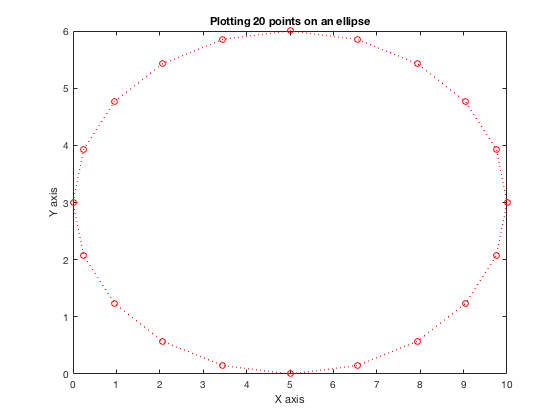

theta = 0:pi/10:2*pi;
x = 5 + 5*cos(theta);
y = 3 + 3*sin(theta);
plot(x,y,'r:o')
xlabel("X axis")
ylabel("Y axis")
title("Plotting 20 points on an ellipse")

**b. Draw a polygon connecting the above points**

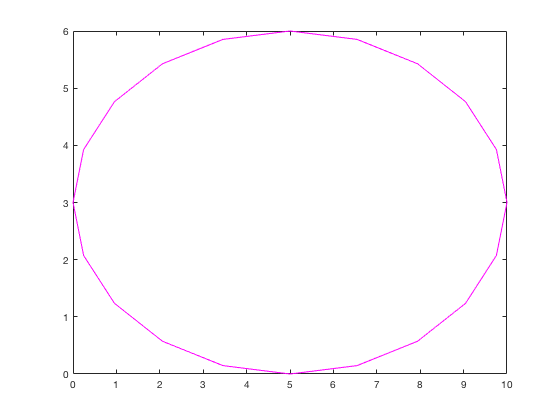

plot(x,y,'m')

**Question 2: (Exercise 2.1)**

Demonstrate how unequal tangent vector magnitude with the symmetric slope end condition would affect the resulting Hermite curves for the following coefficients, where k = 0.5,1,1.5 and 2. Display the results graphically.

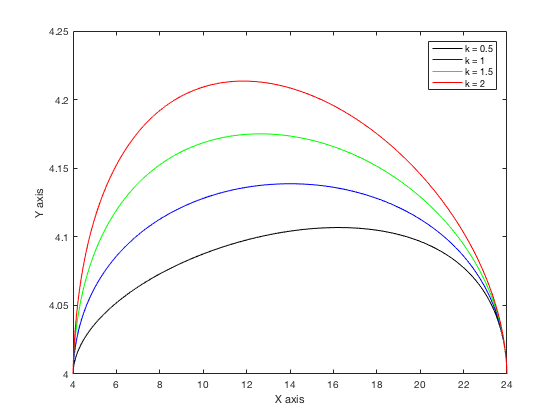

k = [0.5 1 1.5 2];
figure(1); cla;
colorstring = 'kbgr';
u = 0:0.01:1;
for i = 1:size(k,2)
p = [4 4 0;24 4 0;0.8320*k(i) 0.5547*k(i) 0;0.8320 -0.5547 0];
for j = 1:size(u,2)
g = [u(j)^3 u(j)^2 u(j) 1];
A = [2 -2 1 1; -3 3 -2 -1; 0 0 1 0; 1 0 0 0];
x(j) = g*A*p(:,1);
y(j) = g*A*p(:,2);
end
plot(x,y, 'Color', colorstring(i))
xlabel("X axis")
ylabel("Y axis")
hold on
end 
legend("k = 0.5","k = 1","k = 1.5","k = 2")
hold off

Question 3: (Exercise 2.2)

**A  Hermite  curve  is  defined  by  two  points. What is the equation for the curve, i.e.  the polynomial form?  Plot the curve. **

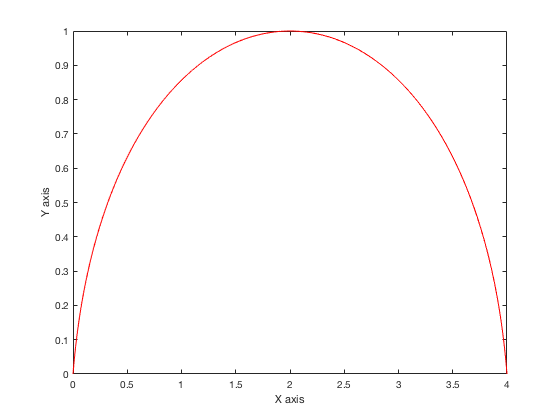

n = 100;
m = 1/(n-1);
t = 0:m:1;
x = -6*t.^3 + 9*t.^2 + t;
y = -4*t.^2 + 4*t;
plot(x,y,'r')
xlabel("X axis")
ylabel("Y axis")